## 1. Draw a line plot that shows the Gaussian probability distribution with mean 50 and standard deviation 10. Label the axes.

% input mean and standard deviation
mu = 50;
sigma = 10;
% create a standard normal distribution object 
% with given mean and the standard deviation:
pd = makedist('Normal', 'mu', mu, 'sigma', sigma);
% the input vector x contains the values at which to calculate the pdf
x = 0:100;
% pdf - probability density function, returns the pdf of the probability 
% distribution object pd, evaluated at the values in x
y = pdf(pd, x);
list = makedist;

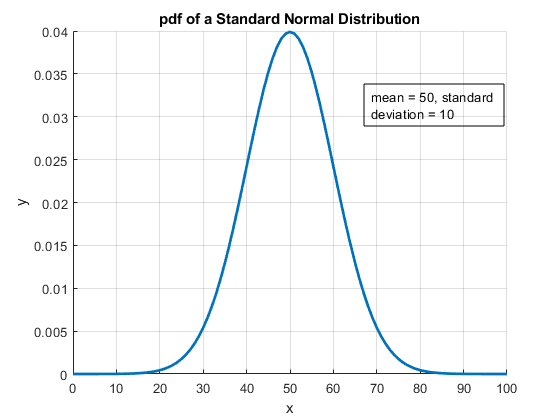

% draw a line plot
figure;
hold on;
plot(x, y, 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('pdf of a Standard Normal Distribution');
annotation('textbox', [.65 .7 .25 .1], 'String', 'mean = 50, standard deviation = 10');
grid;

## 2. The `data1 `variable in Homework2.mat is a matrix of dimensions 3x20. Each row contains measurements obtained for a distinct group of subjects. We are interested in assessing whether there are any differences across the three groups. The metric that we will use is variability in the group means (i.e. compute the mean of each group and then compute the standard deviation across the three mean values). If this variability is high, that would suggest that the groups are different, whereas if the variability is low, that would suggest that the groups are the same. Use randomization to test the null hypothesis that all three groups come from the same underlying distribution. Run 10000 simulations and calculate a one-tailed *p*-value. Echo the computed *p*-value to the screen.

file = matfile('Homework2.mat');
data1 = file.data1;
simulationsCount = 10000;

means = mean(data1, 2);
shuffledStndDevs = zeros(1, simulationsCount);
% calculate means for each of the groups
disp('means:');

means:


disp(means');

    0.2595   -0.1361    0.9165



% calc stn dev of means
stndDev = std(means);
fprintf('standard deviation: %f\n', stndDev);

standard deviation: 0.531689


% merge all the data
mergedData = data1(:);

% randomly divide the given merged data set into 3 groups 
% and calculate the standard deviation of means
% (repeat 10000 times);
for i = 1 : simulationsCount
    
    % shuffle data in merged data and form new 3*20 random matrix
    shuffledData = mergedData(randperm(length(mergedData)));
    shuffledData1 = reshape(shuffledData, 3, 20);
    
    shuffledMeans = mean(shuffledData1, 2);
    
    % one-tailed test will operate with the values of standard deviation;
    shuffledStndDevs(i) = std(shuffledMeans);    
end

% the null hypothesis: all three groups come from the same underlying distribution;
% we accept that fact until the evidence indicates otherwise;

% result p-value will show what part of tests resulted with std' that is significantly
% greater than std value;
% sum() will return the count of element that are greater than stndDev
pValueOT = sum(shuffledStndDevs > stndDev) / simulationsCount;
fprintf('one-tailed p-value: %.5f\n', pValueOT);

one-tailed p-value: 0.00830


## 3. Suppose we measure a group of 100 subjects before and after a certain manipulation. The `data2a `variable in Homework2.mat is a vector of dimensions 1 x 100 with the pre-manipulation measurement, and the `data2b `variable in Homework2.mat is a vector of dimensions 1 x 100 with the post-manipulation measurement. Quantify the manipulation effect by subtracting the pre-manipulation from the post-manipulation measurement. Then use bootstrapping to test the null hypothesis that the differences come from a probability distribution with mean 0. Run 10,000 simulations and calculate a two-tailed *p*-value. Echo the computed *p*-value to the screen.

% pre-manipulation measurements
data2a = file.data2a;
% post-manipulation measurements
data2b = file.data2b;

% substract the pre-data from the post-data
diff = minus(data2b, data2a);
% calculate the actual mean value
actualMean = mean(diff);
calcMeans = zeros(simulationsCount, 1);

% substract from the diff values the mean of itself
substr = diff - mean(diff);

% the null hyp-s: the differences come from a distribution with mean = 0;
% that means that all the bootstrapped vectors will return approximately 
% the same mean values;
% 10000 times: shuffle the dataset and calculate the mean
for i = 1 : simulationsCount
    btstrpVector = getBootstrapVector(substr);
    calcMeans(i) = mean(btstrpVector);
end

% two-tailed p-value:
% since we assume, that values come from a distribution with mean = 0,
% then to calculate two-tailed p-value we will count following values: 
% values(!=0) == values(>0) + values(<0)
pValueTT = sum(abs(calcMeans) > abs(actualMean)) / simulationsCount;
fprintf('two-tailed p-value: %.5f\n', pValueTT);

two-tailed p-value: 0.04340


## 4. Flip a coin *n *times and count the number of heads obtained. Repeat this 10,000 times and visualize the distribution of results using a histogram. Perform this simulation for different *n *values (*n*= 10, 100, 1000) and show the resulting histograms on three different subplots of a single figure. For each subplot, label its axes and provide a title.

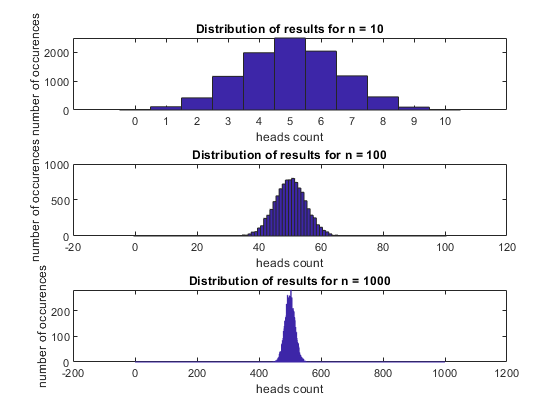

% head = 0; tail = 1;
n = [10, 100, 1000];

% visualize the results for different n as subplots of one figure
figure;
hold on;

% repeat for each of the n values
for i = 1 : length(n)
        
    % generate random indices of n values == random distribution of results
    % (values 0 and 1)
    randomIndices = round(rand(simulationsCount, n(i)));
    % count number of heads for current distribution
    headsCount = sum(randomIndices' == 0);
  
%{
    % -----solution with a for-loop 1:10000-----
    % headsCount - is a 10000 * n-length matrix;
    % each column corresponds to the value of n
    headsCount = zeros(simulationsCount, length(n));
 
     for j = 1 : simulationsCount
         % generate random indices of n values == a random distribution of results
         randomVector1 = round(rand(1, n(i)));
         % count number of heads for current distribution
         headsCount(j, i) = sum(randomVector1 == 1);
     end
    
    hist(headsCount(:, i), 100);
    % -----end of solution-----
%}
    
    subplot(length(n), 1, i);
    %hist(headsCount, 100);
    hist(headsCount, 0:n(i));
    title(sprintf('Distribution of results for n = %d', n(i)));
    xlabel('heads count');
    ylabel('number of occurences');
end

% copy of getBootstrapVector() function from Exercises 1:

function bootstrapVectorOut = getBootstrapVector(vector)
    indices = ceil(length(vector) * rand(length(vector), 1));
    
    bootstrapVectorOut = vector(indices);
end